clear; close all; clc;
rng(0);  % For reproducibility

%% Load data
trainData = readtable('DailyDelhiClimateTrain.csv');
testData  = readtable('DailyDelhiClimateTest.csv');

yTrainAll = trainData.meantemp;
yTestAll  = testData.meantemp;

%% Forward chaining settings
initLen   = 365;   % first fold: 1-year training
stepLen   = 90;    % then roll by 90 days
N         = numel(yTrainAll);

nFolds    = floor((N - initLen) / stepLen);
fprintf('Total folds: %d\n', nFolds);

Total folds: 12



%% Model / config settings
lagListAR   = [10 90 180];   % AR(p) configurations
lagListRNN  = [10 90 180];   % RNN visible history via delays 1:p
nCfg        = numel(lagListAR);

numHiddenRNN  = 16;
numHiddenLSTM = 16;

%% Storage for RMSE
rmseAR_uni    = nan(nFolds, nCfg);   % folds × configs
rmseRNN_uni   = nan(nFolds, nCfg);
rmseLSTM_uni  = nan(nFolds, 1);     % LSTM not dependent on p

%% Forward chaining over folds
for k = 1:nFolds
    
    % Training indices: from day 1 to "1 year + (k-1)*stepLen"
    idxTrain = 1 : (initLen + (k-1)*stepLen);
    
    % Validation indices: the next 'stepLen' days
    idxVal   = (initLen + (k-1)*stepLen + 1) : ...
               (initLen + k*stepLen);
    
    yTrain_raw = yTrainAll(idxTrain);
    yVal_raw   = yTrainAll(idxVal);

    % Normalization (only using training statistics)
    mu  = mean(yTrain_raw);
    sig = std(yTrain_raw);
    if sig == 0, sig = 1; end

    yTrain = (yTrain_raw - mu) / sig;
    yVal   = (yVal_raw   - mu) / sig;

    Ntr = numel(yTrain);

    %% 1. LSTM (fixed config, 1-step ahead)
    XTrainLSTM = {yTrain(1:end-1)'};  % 1×1 cell, row vector
    YTrainLSTM = {yTrain(2:end)'};

    inputSize      = 1;
    numHiddenUnits = numHiddenLSTM;
    outputSize     = 1;

    layers = [ ...
        sequenceInputLayer(inputSize)
        lstmLayer(numHiddenUnits, 'OutputMode','sequence')
        fullyConnectedLayer(outputSize)
        regressionLayer];

    options = trainingOptions('adam', ...
        'MaxEpochs', 60, ...
        'GradientThreshold', 1, ...
        'InitialLearnRate', 0.01, ...
        'Verbose', false, ...
        'Plots', 'none');

    netLSTM = trainNetwork(XTrainLSTM, YTrainLSTM, layers, options);

    % Validation prediction (no warm start here)
    XValLSTM        = {yVal(1:end-1)'};
    YValTrue_LSTMn  = yVal(2:end);

    YPredCell       = predict(netLSTM, XValLSTM, 'MiniBatchSize', 1);
    YValPred_LSTMn  = YPredCell{1}(:)';   % row vector

    % Align lengths
    lenPred = length(YValPred_LSTMn);
    lenTrue = length(YValTrue_LSTMn);
    if lenTrue > lenPred
        YValTrue_LSTMn = YValTrue_LSTMn(end-lenPred+1:end);
    elseif lenPred > lenTrue
        YValPred_LSTMn = YValPred_LSTMn(end-lenTrue+1:end);
    end

    % De-normalize
    YValPred_LSTM = YValPred_LSTMn * sig + mu;
    YValTrue_LSTM = YValTrue_LSTMn * sig + mu;

    YValPred_LSTM = YValPred_LSTM(:)';
    YValTrue_LSTM = YValTrue_LSTM(:)';
    
    rmseLSTM_uni(k) = sqrt(mean((YValPred_LSTM - YValTrue_LSTM).^2));

    %% 2. Loop over different visible history lengths p
    for c = 1:nCfg
        pAR  = lagListAR(c);    % AR(p)
        pRNN = lagListRNN(c);   % RNN delays 1:pRNN

        %% AR(p) baseline via linear regression (fitlm) + warm start
        if Ntr <= pAR + 1
            warning('Fold %d, AR(%d): training length too short. Skipping.', k, pAR);
        else
            % Build lagged design matrix on training segment
            Xtr_AR = zeros(Ntr - pAR, pAR);
            Ytr_AR = yTrain(pAR+1:end);
            for i = 1:pAR
                Xtr_AR(:, i) = yTrain(pAR - i + 1 : end - i);
            end

            mdlAR = fitlm(Xtr_AR, Ytr_AR);

            % One-step Ahead Prediction (Teacher Forcing)
            
            % Concatenate full ground truth data (Train + Val)
            y_true_all = [yTrain; yVal];

            % Initialize container for validation predictions
            YValPred_AR_norm = zeros(numel(yVal), 1);

            % Loop over each time step in the validation set
            for t = 1:numel(yVal)
                idxEnd   = Ntr + t - 1;
                idxStart = idxEnd - pAR + 1;

                % Extract lag features from the Ground Truth array
                lastVals = y_true_all(idxStart:idxEnd);
                lastVals = lastVals(:)';   % Ensure row vector for predict function

                % One-step prediction: Predict current value using actual history
                YValPred_AR_norm(t) = predict(mdlAR, lastVals);
            end

            YValTrue_norm = yVal;

            % Align lengths (Safety check, though lengths should match now)
            lenPred = length(YValPred_AR_norm);
            lenTrue = length(YValTrue_norm);
            if lenTrue > lenPred
                YValTrue_norm = YValTrue_norm(end-lenPred+1:end);
            elseif lenPred > lenTrue
                YValPred_AR_norm = YValPred_AR_norm(end-lenTrue+1:end);
            end

            % De-normalize
            YValPred_AR = YValPred_AR_norm * sig + mu;
            YValTrue    = YValTrue_norm * sig + mu;

            rmseAR_uni(k, c) = sqrt(mean((YValPred_AR - YValTrue).^2));
        end

        %% 2.2) RNN (layrecnet) with delays 1:pRNN + warm start
        if Ntr <= pRNN + 2
            warning('Fold %d, RNN(p=%d): training length too short. Skipping.', k, pRNN);
        else
            % Train on training segment
            X_rnn = num2cell(yTrain(1:end-1)');
            T_rnn = num2cell(yTrain(2:end)');

            netRNN = layrecnet(1:pRNN, numHiddenRNN);
            netRNN.trainFcn = 'trainscg';       % lighter than trainlm
            netRNN.trainParam.showWindow = false;

            [Xs_rnn, Xi_rnn, Ai_rnn, Ts_rnn] = preparets(netRNN, X_rnn, T_rnn);
            netRNN = train(netRNN, Xs_rnn, Ts_rnn, Xi_rnn, Ai_rnn);

            [~, Xf_rnn, Af_rnn] = netRNN(Xs_rnn, Xi_rnn, Ai_rnn);

            % Warm-started validation prediction
            if Ntr < pRNN
                warmTail = yTrain;
            else
                warmTail = yTrain(end-pRNN:end);
            end

            seqAll = [warmTail; yVal];
            X_all  = num2cell(seqAll(1:end-1)');
            T_all  = num2cell(seqAll(2:end)');

            [Xs2_rnn, ~, ~, ~] = preparets(netRNN, X_all, {});
            Y_all_rnn = netRNN(Xs2_rnn, Xf_rnn, Af_rnn);
            Y_all_rnn = cell2mat(Y_all_rnn)';

            nVal = numel(yVal);
            if length(Y_all_rnn) < nVal
                YValPred_rnn_norm = Y_all_rnn;
                YValTrue_rnn_norm = yVal(end-length(Y_all_rnn)+1:end);
            else
                YValPred_rnn_norm = Y_all_rnn(end-nVal+1:end);
                YValTrue_rnn_norm = yVal;
            end

            % De-normalize
            YValPred_RNN = YValPred_rnn_norm * sig + mu;
            YValTrue_RNN = YValTrue_rnn_norm * sig + mu;

            rmseRNN_uni(k, c) = sqrt(mean((YValPred_RNN - YValTrue_RNN).^2));
        end
    end

    %% Fold summary print
    fprintf("Fold %2d | LSTM RMSE = %.4f\n", k, rmseLSTM_uni(k));
    for c = 1:nCfg
        fprintf("   Config p=%3d | AR RMSE = %.4f | RNN RMSE = %.4f\n", ...
            lagListAR(c), rmseAR_uni(k,c), rmseRNN_uni(k,c));
    end
end

Fold  1 | LSTM RMSE = 1.5677


   Config p= 10 | AR RMSE = 2.5087 | RNN RMSE = 1.5456
   Config p= 90 | AR RMSE = 9.0409 | RNN RMSE = 4.6805
   Config p=180 | AR RMSE = 10.1273 | RNN RMSE = 4.9136


Fold  2 | LSTM RMSE = 1.7275


   Config p= 10 | AR RMSE = 3.0598 | RNN RMSE = 1.6535
   Config p= 90 | AR RMSE = 14.6906 | RNN RMSE = 4.0683
   Config p=180 | AR RMSE = 13.9059 | RNN RMSE = 8.6192


Fold  3 | LSTM RMSE = 1.5520


   Config p= 10 | AR RMSE = 2.6911 | RNN RMSE = 1.8576
   Config p= 90 | AR RMSE = 4.4942 | RNN RMSE = 4.2910
   Config p=180 | AR RMSE = 15.0747 | RNN RMSE = 4.4257


Fold  4 | LSTM RMSE = 1.8541


   Config p= 10 | AR RMSE = 3.5602 | RNN RMSE = 2.8248
   Config p= 90 | AR RMSE = 11.1807 | RNN RMSE = 10.7123
   Config p=180 | AR RMSE = 13.0034 | RNN RMSE = 23.9213


Fold  5 | LSTM RMSE = 1.7279


   Config p= 10 | AR RMSE = 3.3128 | RNN RMSE = 1.4439
   Config p= 90 | AR RMSE = 10.7923 | RNN RMSE = 2.9813
   Config p=180 | AR RMSE = 15.2972 | RNN RMSE = 8.3037


Fold  6 | LSTM RMSE = 2.0892


   Config p= 10 | AR RMSE = 3.6605 | RNN RMSE = 2.0376
   Config p= 90 | AR RMSE = 14.6305 | RNN RMSE = 5.9862
   Config p=180 | AR RMSE = 13.1150 | RNN RMSE = 4.6057


Fold  7 | LSTM RMSE = 1.5437


   Config p= 10 | AR RMSE = 2.3576 | RNN RMSE = 1.8632
   Config p= 90 | AR RMSE = 4.1154 | RNN RMSE = 2.4786
   Config p=180 | AR RMSE = 14.4478 | RNN RMSE = 6.3319


Fold  8 | LSTM RMSE = 1.2407


   Config p= 10 | AR RMSE = 2.6420 | RNN RMSE = 1.1598
   Config p= 90 | AR RMSE = 10.1486 | RNN RMSE = 1.6112
   Config p=180 | AR RMSE = 11.8505 | RNN RMSE = 2.8627


Fold  9 | LSTM RMSE = 1.6357


   Config p= 10 | AR RMSE = 2.9136 | RNN RMSE = 23.1715
   Config p= 90 | AR RMSE = 10.3184 | RNN RMSE = 3.0132
   Config p=180 | AR RMSE = 13.0972 | RNN RMSE = 3.7901


Fold 10 | LSTM RMSE = 1.9016


   Config p= 10 | AR RMSE = 3.2417 | RNN RMSE = 1.7545
   Config p= 90 | AR RMSE = 15.4301 | RNN RMSE = 2.6351
   Config p=180 | AR RMSE = 13.3706 | RNN RMSE = 5.0391


Fold 11 | LSTM RMSE = 1.6904


   Config p= 10 | AR RMSE = 2.5893 | RNN RMSE = 1.6562
   Config p= 90 | AR RMSE = 4.6932 | RNN RMSE = 1.6825
   Config p=180 | AR RMSE = 14.0961 | RNN RMSE = 2.4631


Fold 12 | LSTM RMSE = 1.2703


   Config p= 10 | AR RMSE = 2.1309 | RNN RMSE = 1.0796
   Config p= 90 | AR RMSE = 7.3064 | RNN RMSE = 1.4318
   Config p=180 | AR RMSE = 10.1718 | RNN RMSE = 3.0433


%% Overall RMSE summary (mean over folds)
meanAR   = mean(rmseAR_uni, 1, 'omitnan');
meanRNN  = mean(rmseRNN_uni, 1, 'omitnan');
meanRNN  = mean(rmseRNN_uni, 1, 'omitnan');
meanLSTM = mean(rmseLSTM_uni, 1, 'omitnan');

fprintf("\n=== Univariate forward-chaining (year+90d blocks) RMSE (mean over folds) ===\n");


=== Univariate forward-chaining (year+90d blocks) RMSE (mean over folds) ===


for c = 1:nCfg
    fprintf("AR(%3d) : %.4f\n", lagListAR(c),  meanAR(c));
end

AR( 10) : 2.8890
AR( 90) : 9.7368
AR(180) : 13.1298


for c = 1:nCfg
    fprintf("RNN(1:%3d) : %.4f\n", lagListRNN(c),  meanRNN(c));
end

RNN(1: 10) : 3.5040
RNN(1: 90) : 3.7977
RNN(1:180) : 6.5266


fprintf("LSTM (fixed config) : %.4f\n", meanLSTM);

LSTM (fixed config) : 1.6501


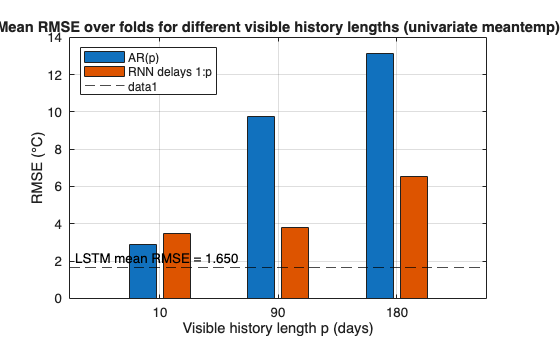


%% mean RMSE vs visible history length (bar chart)
figure;

xCats = categorical(string(lagListAR));
xCats = reordercats(xCats, string(lagListAR));

barData = [meanAR(:) meanRNN(:)];   % nCfg × 2
bar(xCats, barData);
ylabel('RMSE (°C)');
xlabel('Visible history length p (days)');
title('Mean RMSE over folds for different visible history lengths (univariate meantemp)');
legend({'AR(p)','RNN delays 1:p'}, 'Location','northwest');
grid on;
hold on;

yline(meanLSTM, '--k', sprintf('LSTM mean RMSE = %.3f', meanLSTM), ...
    'LabelHorizontalAlignment','left');

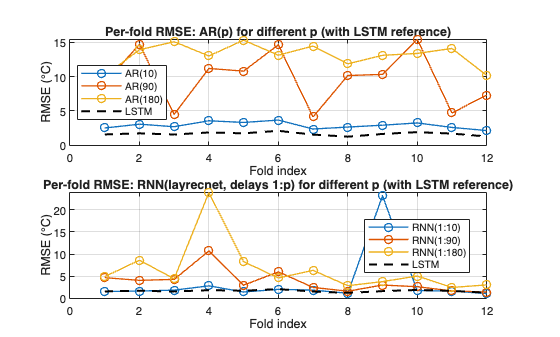


%% per-fold RMSE curves
figure;
tFolds = 1:nFolds;

% AR curves
subplot(2,1,1);
plot(tFolds, rmseAR_uni, '-o', 'LineWidth', 1); hold on;
plot(tFolds, rmseLSTM_uni, 'k--', 'LineWidth', 1.5);
grid on;
xlabel('Fold index');
ylabel('RMSE (°C)');
title('Per-fold RMSE: AR(p) for different p (with LSTM reference)');
legendStrings = arrayfun(@(p)sprintf('AR(%d)',p), lagListAR, 'UniformOutput', false);
legend([legendStrings {'LSTM'}], 'Location','best');

% RNN curves
subplot(2,1,2);
plot(tFolds, rmseRNN_uni, '-o', 'LineWidth', 1); hold on;
plot(tFolds, rmseLSTM_uni, 'k--', 'LineWidth', 1.5);
grid on;
xlabel('Fold index');
ylabel('RMSE (°C)');
title('Per-fold RMSE: RNN(layrecnet, delays 1:p) for different p (with LSTM reference)');
legendStringsR = arrayfun(@(p)sprintf('RNN(1:%d)',p), lagListRNN, 'UniformOutput', false);
legend([legendStringsR {'LSTM'}], 'Location','best');

clear; close all; clc;
rng(0);  % For reproducibility

%% Load data
trainData = readtable('DailyDelhiClimateTrain.csv');
testData  = readtable('DailyDelhiClimateTest.csv');

yTrainAll = trainData.meantemp;
yTestAll  = testData.meantemp;

%% Final comparison on TEST set (AR vs RNN vs LSTM with warm start for AR & RNN)

% 1. Normalization based on TRAIN only 
mu  = mean(yTrainAll);
sig = std(yTrainAll);
if sig == 0, sig = 1; end

yTrain = (yTrainAll - mu) / sig;
yTest  = (yTestAll  - mu) / sig;

%% 2. AR(90) baseline on test set (recursive, warm start)

noLagsAR = 90;
Ntr = numel(yTrain);

if Ntr <= noLagsAR + 1
    error("Training series too short for AR(%d).", noLagsAR);
end

% build AR training set on train data
Xtr_AR = zeros(Ntr - noLagsAR, noLagsAR);
Ytr_AR = yTrain(noLagsAR+1:end);

for i = 1:noLagsAR
    Xtr_AR(:, i) = yTrain(noLagsAR - i + 1 : end - i);
end

mdlAR = fitlm(Xtr_AR, Ytr_AR);

% one step
y_true_all = [yTrain; yTest]; 
Y_AR_test_norm = zeros(numel(yTest), 1);

for t = 1:numel(yTest)
    lastVals = y_true_all(Ntr + t - (1:noLagsAR));
    lastVals = lastVals(:)';      % row vector
    
    % one step prediction
    Y_AR_test_norm(t) = predict(mdlAR, lastVals);
end

%% 3. RNN (layrecnet, delays 1:90) on test set with warm start

% 1-step ahead training on train data
X_rnn = num2cell(yTrain(1:end-1)');
T_rnn = num2cell(yTrain(2:end)');

numHiddenRNN = 16;
pRNN         = 90;
netRNN = layrecnet(1:pRNN, numHiddenRNN);
netRNN.trainFcn = 'trainscg';
netRNN.trainParam.showWindow = false;

[Xs_rnn, Xi_rnn, Ai_rnn, Ts_rnn] = preparets(netRNN, X_rnn, T_rnn);
netRNN = train(netRNN, Xs_rnn, Ts_rnn, Xi_rnn, Ai_rnn);

[~, Xf_rnn, Af_rnn] = netRNN(Xs_rnn, Xi_rnn, Ai_rnn);

contextLen = pRNN;
if Ntr < contextLen
    error('Train series shorter than RNN context length.');
end

yContext      = yTrain(end-contextLen:end);
yInput_all    = [yContext; yTest];          % (contextLen + length(test)) × 1
XTest_rnn_all = num2cell(yInput_all(1:end-1)');

[Xs2_rnn, ~, ~, ~] = preparets(netRNN, XTest_rnn_all, {});
Y_all_rnn_norm = netRNN(Xs2_rnn, Xf_rnn, Af_rnn);
Y_all_rnn_norm = cell2mat(Y_all_rnn_norm)';  % length = contextLen + length(test) - 1

nTestSteps       = length(yTest) - 1;
Y_RNN_test_norm  = Y_all_rnn_norm(end-nTestSteps+1:end);
YTrue_rnn_test   = yTest(2:end);

%% 4. LSTM on test set (no explicit window, 1-step ahead)

XTrainLSTM = {yTrain(1:end-1)'};
YTrainLSTM = {yTrain(2:end)'};

numHiddenLSTM = 16;

layers = [ ...
    sequenceInputLayer(1)
    lstmLayer(numHiddenLSTM,'OutputMode','sequence')
    fullyConnectedLayer(1)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs', 60, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.01, ...
    'Verbose', false, ...
    'Plots', 'none');

netLSTM = trainNetwork(XTrainLSTM, YTrainLSTM, layers, options);

XTestLSTM        = {yTest(1:end-1)'};
YTrue_LSTM_testn = yTest(2:end);

Y_test_cell      = predict(netLSTM, XTestLSTM, 'MiniBatchSize', 1);
Y_LSTM_test_norm = Y_test_cell{1}(:)';

%% RMSE

lenAR   = length(Y_AR_test_norm);
lenRNN  = length(Y_RNN_test_norm);
lenLSTM = length(Y_LSTM_test_norm);
lenT    = length(YTrue_rnn_test);

L = min([lenAR, lenRNN, lenLSTM, lenT]);

Y_AR_test_norm   = Y_AR_test_norm(end-L+1:end);
Y_RNN_test_norm  = Y_RNN_test_norm(end-L+1:end);
Y_LSTM_test_norm = Y_LSTM_test_norm(end-L+1:end);
Y_true_test_norm = YTrue_rnn_test(end-L+1:end);

Y_AR_test   = Y_AR_test_norm   * sig + mu;
Y_RNN_test  = Y_RNN_test_norm  * sig + mu;
Y_LSTM_test = Y_LSTM_test_norm * sig + mu;
Y_LSTM_test = Y_LSTM_test(:);
Y_true_test = Y_true_test_norm * sig + mu;

% RMSE
rmseAR   = sqrt(mean((Y_AR_test   - Y_true_test).^2));
rmseRNN  = sqrt(mean((Y_RNN_test  - Y_true_test).^2));
rmseLSTM = sqrt(mean((Y_LSTM_test - Y_true_test).^2));

fprintf('Test RMSE | AR(90)=%.4f | RNN(1:90)=%.4f | LSTM=%.4f\n', rmseAR, rmseRNN, rmseLSTM);

Test RMSE | AR(90)=1.6991 | RNN(1:90)=3.4039 | LSTM=1.6918


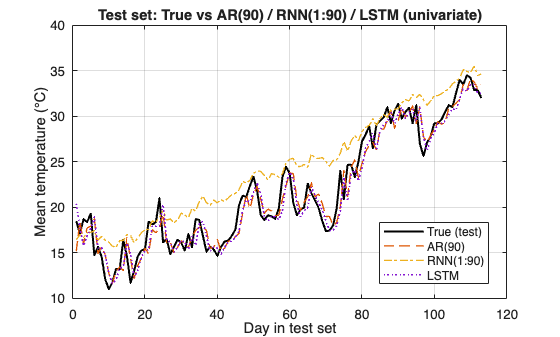


%% Plot

figure;
plot(Y_true_test, 'k', 'LineWidth', 1.5); hold on;
plot(Y_AR_test,   '--', 'LineWidth', 1);
plot(Y_RNN_test,  '-.', 'LineWidth', 1);
plot(Y_LSTM_test, ':',  'LineWidth', 1.2);

legend('True (test)','AR(90)','RNN(1:90)','LSTM','Location','best');
xlabel('Day in test set');
ylabel('Mean temperature (°C)');
title('Test set: True vs AR(90) / RNN(1:90) / LSTM (univariate)');
grid on;

varsTrain = [trainData.meantemp, trainData.humidity, ...
             trainData.wind_speed, trainData.meanpressure];
varsTest  = [testData.meantemp,  testData.humidity, ...
             testData.wind_speed, testData.meanpressure];

% Prediction target: next-day mean temperature
yTrainAll = trainData.meantemp;
yTestAll  = testData.meantemp;

[numTrain, numVars] = size(varsTrain);

%% Normalization (per variable, using TRAIN only)
muX  = mean(varsTrain, 1);
sigX = std(varsTrain, 0, 1); 
sigX(sigX == 0) = 1;

XTrain = (varsTrain - muX) ./ sigX;      % numTrain × numVars
XTest  = (varsTest  - muX) ./ sigX;

muy  = mean(yTrainAll);
sigy = std(yTrainAll); 
if sigy == 0, sigy = 1; end

yTrain = (yTrainAll - muy) / sigy;
yTest  = (yTestAll  - muy) / sigy;

%% Multivariate AR baseline ( VAR-like, with lags on all variables )
pAR = 90;                     % visible history length
Ntr = numTrain;               % number of train observations

if Ntr <= pAR + 1
    error("Training series too short for AR(%d).", pAR);
end

% Design matrix: [x(t-1), x(t-2), ... x(t-pAR)] for all 4 variables
% Size: (Ntr - pAR) × (pAR * numVars)
Xtr_AR = zeros(Ntr - pAR, pAR * numVars);
Ytr_AR = yTrain(pAR+1:end);      % predict y(t) from past X's

for lag = 1:pAR
    % slice rows pAR-lag+1 : Ntr-lag, take all variables
    block = XTrain(pAR - lag + 1 : end - lag, :);   % (Ntr - pAR) × numVars
    colIdx = (lag-1)*numVars + (1:numVars);         % columns for this lag
    Xtr_AR(:, colIdx) = block;
end

mdlAR = fitlm(Xtr_AR, Ytr_AR);

% Recursive multi-step forecast on test set (normalized)
y_all = [yTrain; zeros(numel(yTest),1)];    % concat train + placeholder
X_all = [XTrain; XTest];                    % full normalized inputs

for t = 1:numel(yTest)
    idxEnd   = Ntr + t - 1;
    idxStart = idxEnd - pAR + 1;
    window   = X_all(idxStart:idxEnd, :);   % pAR × numVars
    
    % build 1 row: [x(t-1), x(t-2), ...]
    xRow = flipud(window);                  % (pAR × numVars), reverse in time
    xRow = reshape(xRow.', 1, []);          % 1 × (pAR * numVars)
    
    y_all(Ntr + t) = predict(mdlAR, xRow);
end

Y_AR_test_norm = y_all(Ntr+1:end);   % length = length(yTest)
Y_AR_test      = Y_AR_test_norm * sigy + muy;

%% Multivariate RNN (layrecnet) — inputs are 4-dim vectors

% Build sequence: at each time step t, input is 4×1 vector XTrain(t,:)',
% target is scalar yTrain(t+1)
X_rnn = cell(1, Ntr-1);      % 1×T cell, each 4×1
T_rnn = cell(1, Ntr-1);      % 1×T cell, each 1×1

for t = 1:Ntr-1
    X_rnn{t} = XTrain(t, :)';    % 4×1
    T_rnn{t} = yTrain(t+1);      % scalar
end

pRNN         = 90;          % delays 1:pRNN
numHiddenRNN = 16;

netRNN = layrecnet(1:pRNN, numHiddenRNN);
netRNN.trainFcn = 'trainscg';
netRNN.trainParam.showWindow = false;

[Xs_rnn, Xi_rnn, Ai_rnn, Ts_rnn] = preparets(netRNN, X_rnn, T_rnn);
netRNN = train(netRNN, Xs_rnn, Ts_rnn, Xi_rnn, Ai_rnn);

% Test prediction with warm start
% Input at each step is still 4×1 vector.
contextLen = pRNN;
if Ntr < contextLen
    error('Train series shorter than RNN context length.');
end

XContext = XTrain(end-contextLen+1:end, :);
XallTest = [XContext; XTest];          % (contextLen + length(test)) × 4
TSteps   = size(XallTest,1);

X_test_seq = cell(1, TSteps-1);
for t = 1:TSteps-1
    X_test_seq{t} = XallTest(t, :)';    % 4×1
end

[Xs2_rnn, Xi2_rnn, Ai2_rnn, ~] = preparets(netRNN, X_test_seq, {});
Y_all_rnn_norm = netRNN(Xs2_rnn, Xi2_rnn, Ai2_rnn);
Y_all_rnn_norm = cell2mat(Y_all_rnn_norm)';   % length = TSteps-1

% keep last length(yTest)-1 predictions as test one-step forecasts
nTestSteps       = length(yTest) - 1;
Y_RNN_test_norm  = Y_all_rnn_norm(end-nTestSteps+1:end);
Y_true_rnn_norm  = yTest(2:end);

Y_RNN_test = Y_RNN_test_norm * sigy + muy;
Y_true_rnn = Y_true_rnn_norm * sigy + muy;

%% Multivariate LSTM — 4-channel input, 1-dim output

% Sequence format: 1 cell, inside is [numChannels × sequenceLength]
XTrainLSTM = {XTrain(1:end-1,:)'};    % 4 × (Ntr-1)
YTrainLSTM = {yTrain(2:end)'};        % 1 × (Ntr-1)

inputSize      = numVars;     % 4 channels
numHiddenLSTM  = 16;
outputSize     = 1;

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenLSTM,'OutputMode','sequence')
    fullyConnectedLayer(outputSize)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs', 60, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.01, ...
    'Verbose', false, ...
    'Plots', 'none');

netLSTM = trainNetwork(XTrainLSTM, YTrainLSTM, layers, options);

% Test sequence
XTestLSTM        = {XTest(1:end-1,:)'};   % 4 × (Ntest-1)
YTrue_LSTM_norm  = yTest(2:end);

YPredCell        = predict(netLSTM, XTestLSTM, 'MiniBatchSize', 1);
Y_LSTM_test_norm = YPredCell{1}(:)';       % row

Y_LSTM_test = Y_LSTM_test_norm * sigy + muy;
Y_true_LSTM = YTrue_LSTM_norm * sigy + muy;

%% Align lengths & compute RMSE

% AR has length = length(yTest), RNN/LSTM length = length(yTest)-1
lenAR   = length(Y_AR_test);
lenRNN  = length(Y_RNN_test);
lenLSTM = length(Y_LSTM_test);
lenT    = length(Y_true_LSTM);   % = length(yTest)-1

L = min([lenAR, lenRNN, lenLSTM, lenT]);

Y_AR_test   = Y_AR_test(end-L+1:end);
Y_RNN_test  = Y_RNN_test(end-L+1:end);
Y_LSTM_test = Y_LSTM_test(end-L+1:end);
Y_LSTM_test = Y_LSTM_test(:);
Y_true_test = Y_true_LSTM(end-L+1:end);

rmseAR   = sqrt(mean((Y_AR_test   - Y_true_test).^2));
rmseRNN  = sqrt(mean((Y_RNN_test  - Y_true_test).^2));
rmseLSTM = sqrt(mean((Y_LSTM_test - Y_true_test).^2));

fprintf('Multivariate test RMSE | AR(p=%d)=%.4f | RNN(1:%d)=%.4f | LSTM=%.4f\n', ...
        pAR, rmseAR, pRNN, rmseRNN, rmseLSTM);

Multivariate test RMSE | AR(p=90)=1.8157 | RNN(1:90)=7.5342 | LSTM=1.7507


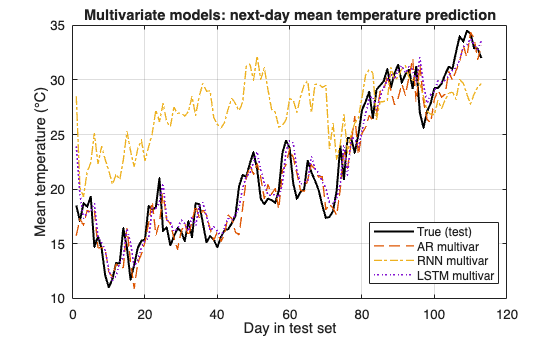


%% Plot: test truth vs three models (multivariate inputs)
figure;
plot(Y_true_test, 'k', 'LineWidth', 1.5); hold on;
plot(Y_AR_test,   '--', 'LineWidth', 1);
plot(Y_RNN_test,  '-.', 'LineWidth', 1);
plot(Y_LSTM_test, ':',  'LineWidth', 1.2);
legend('True (test)','AR multivar','RNN multivar','LSTM multivar','Location','best');
xlabel('Day in test set');
ylabel('Mean temperature (°C)');
title('Multivariate models: next-day mean temperature prediction');
grid on;